# Devoir 2-bonjour hiiiiiii

## Initialisation

clc
clear all
close all

## 1 Limites de l'enveloppe de vol - Laboratoires #2 et #3

## Mise en mémoire des données

run('aircraft_data.m')

## 1.1

%
% Condition de vol
Ma_e = 0.2;
h_e  = 1500;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 1.1917e-10


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.3490

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.4052

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 4.3817e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 0.2523


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 19.9976

dths_e_d = dths_e*180/pi

dths_e_d = 23.2168

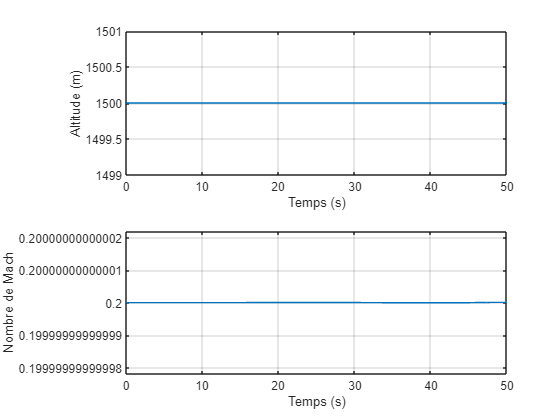


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.2

%
%
% Condition de vol
Ma_e = 0.85;
h_e  = 7000;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 5.8208e-11


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.0208

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.0072

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 5.5161e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 0.5467


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 1.1904

dths_e_d = dths_e*180/pi

dths_e_d = 0.4146

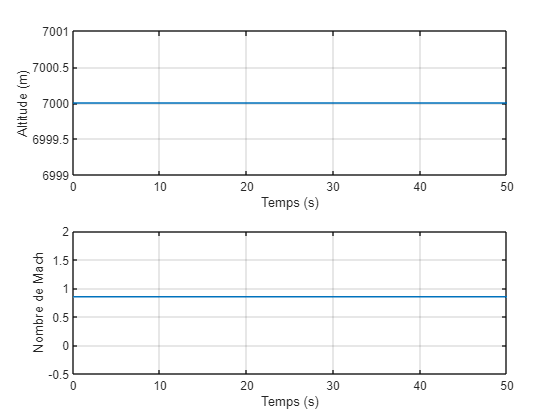


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.3

%
%
% Condition de vol
Ma_e = 0.45;
h_e  = 11000;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 2.1828e-11


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.2548

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.2932

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 3.5662e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 1.1003


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 14.6004

dths_e_d = dths_e*180/pi

dths_e_d = 16.7998

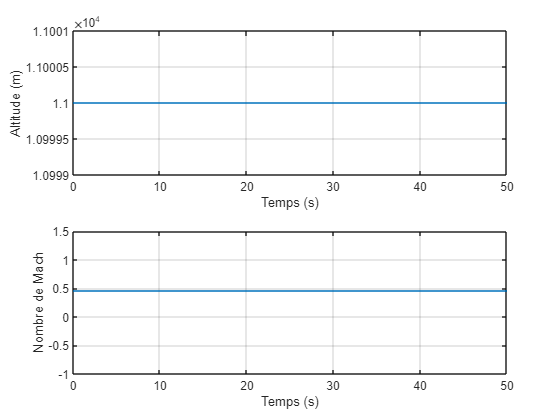


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.4

%

## 1.5

%

## 2 Analyse d’un modèle d’état linéarisé - Laboratoire #4

## Mise en mémoire des données

%load rapport_2_data.mat

## 2.1

% 

## 2.2

% 

## 2.3

% 

## 2.4

% 

## 2.5

% 

## 2.6

% 

## 2.7

% 

## 2.8

% 

## 2.9

% 

## 2.10

% 